WeightedLOB= readtable('/Users/lynnxt/Desktop/WeightedLOB.xlsx');
WeightedLOB

WeightedLOB = 18129×5 table
    SourceTime    Weighted_Bid_Price    Weighted_Ask_Price    MidPrice      State   
    __________    __________________    __________________    ________    __________

     0.38204            149.34                134.36           141.85     {'Static'}
     0.39545            142.07                141.58           141.82     {'Down'  }
     0.39583            147.63                137.08           142.36     {'Up'    }
     0.39584            142.14                141.41           141.77     {'Down'  }
     0.39586            141.88                140.79           141.34     {'Down'  }
     0.39587            141.84                141.63           141.73     {'Up'    }
     0.39588               NaN                 140.2              NaN     {'Static'}
     0.39589             141.7                141.68           141.69     {'Static'}
     0.39591            142.27                141.44           141.85     {'Up'    }
     0.39593            145.99      

% Create features and target variables
features = table();
features.SourceTime = WeightedLOB.SourceTime;
features.Weighted_Bid_Price = WeightedLOB.Weighted_Bid_Price;
features.Weighted_Ask_Price = WeightedLOB.Weighted_Ask_Price;
features.MidPrice = WeightedLOB.MidPrice;

% Create lagged features (previous 30 minutes)
windowSize = 30 * 60; % 30 minutes in seconds
features.LaggedWeightedBid = lagmatrix(WeightedLOB.Weighted_Bid_Price, 1:windowSize);
features.LaggedWeightedAsk = lagmatrix(WeightedLOB.Weighted_Ask_Price, 1:windowSize);
features.LaggedMidPrice = lagmatrix(WeightedLOB.MidPrice, 1:windowSize);

% Shift the State column to represent the next 10 seconds' state
features.TargetState = circshift(WeightedLOB.State, -10);

% Remove rows with NaN resulting from lag operations
features(any(isnan(features.LaggedWeightedBid), 2), :) = [];
features(any(isnan(features.LaggedWeightedAsk), 2), :) = [];
features(any(isnan(features.LaggedMidPrice), 2), :) = [];
% Assuming TargetState is categorical, we convert it to string to check for missing entries
features(any(ismissing(categorical(features.TargetState)), 2), :) = [];



% Split the data into training and testing sets
splitRatio = 0.8;
splitIndex = round(splitRatio * size(features, 1));
trainData = features(1:splitIndex, :);
testData = features(splitIndex+1:end, :);

% Train the Random Forest model
rng(1); % Set seed for reproducibility
X = [trainData.LaggedWeightedBid, trainData.LaggedWeightedAsk, trainData.LaggedMidPrice];
Y = categorical(trainData.TargetState);
mdl = TreeBagger(100, X, Y, 'Method', 'classification');


% Predict on the test set
XTest = [testData.LaggedWeightedBid, testData.LaggedWeightedAsk, testData.LaggedMidPrice];
YTestPred = predict(mdl, XTest);
% Convert the cell array predictions to categorical for comparison
YTestPred = categorical(YTestPred);

% Evaluate the accuracy
accuracy = sum(YTestPred == testData.TargetState) / numel(testData.TargetState);
disp(['Accuracy on Test Set: ' num2str(accuracy)]);

Accuracy on Test Set: 0.49786


% Predict on the test set using Random Forest model
YTestPred_RF = predict(mdl, XTest);
YTestPred_RF = categorical(cellstr(YTestPred_RF)); % Convert predictions to categorical

% Evaluate the accuracy
accuracy_RF = sum(YTestPred_RF == testData.TargetState) / numel(testData.TargetState);
disp(['Random Forest Accuracy on Test Set: ' num2str(accuracy_RF)]);

Random Forest Accuracy on Test Set: 0.49786



% Evaluate the confusion matrix
confMat_RF = confusionmat(categorical(testData.TargetState), YTestPred_RF);

% Extract the scores
truePositive_RF = confMat_RF(1, 1);
trueNegative_RF = confMat_RF(2, 2);
falsePositive_RF = confMat_RF(2, 1);
falseNegative_RF = confMat_RF(1, 2);

% Calculate Accuracy, Precision, Recall, and F1 Score for Random Forest
accuracy_RF = (truePositive_RF + trueNegative_RF) / sum(confMat_RF(:));
precision_RF = truePositive_RF / (truePositive_RF + falsePositive_RF);
recall_RF = truePositive_RF / (truePositive_RF + falseNegative_RF);
f1Score_RF = 2 * (precision_RF * recall_RF) / (precision_RF + recall_RF);

% Display the results
disp(['Random Forest Accuracy: ' num2str(accuracy_RF)]);

Random Forest Accuracy: 0.21276


disp(['Random Forest Precision: ' num2str(precision_RF)]);

Random Forest Precision: 0.95946


disp(['Random Forest Recall: ' num2str(recall_RF)]);

Random Forest Recall: 1


disp(['Random Forest F1 Score: ' num2str(f1Score_RF)]);

Random Forest F1 Score: 0.97931



% Create a table with scores for Random Forest
scoreTable_RF = table(accuracy_RF, precision_RF, recall_RF, f1Score_RF, 'VariableNames', {'Accuracy', 'Precision', 'Recall', 'F1Score'});
disp(scoreTable_RF)

    Accuracy    Precision    Recall    F1Score
    ________    _________    ______    _______

    0.21276      0.95946       1       0.97931



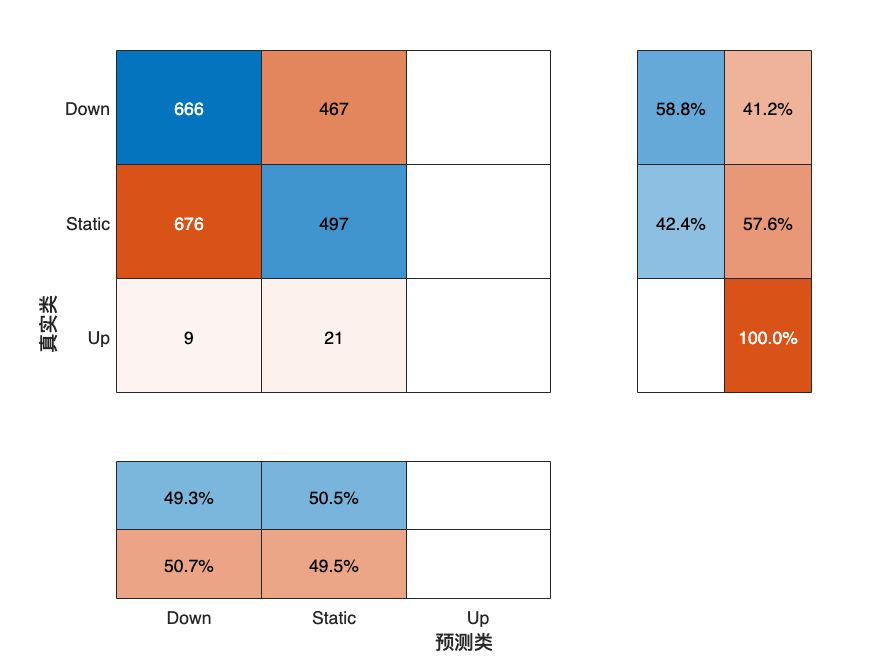


% Create a confusion matrix chart for Random Forest
figure;
confusionchart(confMat_RF, {'Static', 'Up', 'Down'}, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');